% Load image
A = imread('WnR.jpeg');
A = A(144:288, 153:306,:);
subplot(1,2,1), imshow(A)

[n,m,l] = size(A);
NM = n*m;

% Define labels
L = [1, 2, 3, 4, 5]; % 1 - cone, 2 - green, 3 - blue, 4 - purple, 5 - white
% Define seeds
S = [132, 110, 1; 143, 83, 1; 119, 121, 1; 
    24, 17, 2; 103, 52, 2; 72, 103, 2; 31, 149, 2; 12, 39, 2; 94, 115, 2; 91, 129, 2; 115, 98, 2; 142, 3, 2; 10, 12, 2; 80, 92, 2; 89, 63, 2;
    66, 12, 3; 137, 28, 3; 60, 140, 3; 28, 127, 3; 28, 59, 3; 142, 113, 3; 45, 35, 3; 101, 82, 3; 12, 78, 3; 9, 149, 3; 127, 2, 3; 
    93, 33, 4; 15, 106, 4; 125, 70, 4; 55, 77, 4; 36, 102, 4; 137, 55, 4; 130, 82, 4; 110, 77, 4; 67, 70, 4; 144, 20, 4; 137, 10, 4;
    144, 153, 5; 85, 150, 5; 112, 132, 5];
c = [A(132, 110, :); A(24, 17, :); A(66, 12, :); A(93, 33, :); A(144, 153, :)]; c = reshape(c,5,3); c = double(c);

hold on
plot(S(:,2), S(:,1), 'o', 'Color', 'red')
hold off

T = 5000; % Number of steps
img = double(A);

tic
W = sparse(calculate_weights(img,150));
toc

Elapsed time is 4.314638 seconds.


tic
H = construct_hamiltonian(W, 0.001);
toc

Elapsed time is 4.646631 seconds.


tic
for i = 1:numel(L) % use parfor if available
    sprintf("Working with label: %d", i)
    subset = seeds_subset(S,L(i));
    subset_length = size(subset,1);
    A_sub = zeros(NM,1);
    for p = 1:subset_length
        if subset(p,2) + m*(subset(p,1)-1) > numel(A)
            p
            subset(p,2) + m*(subset(p,1)-1)
        end
        A_sub( subset(p,2) + m*(subset(p,1)-1) ) = 1;
    end
    state = 1/sqrt(subset_length) * sparse(A_sub);
    sprintf("The norm of our intial state vector is: %d", dot(full(state), full(state)))
    state = update_state(-T*1i, H, state);
    D(:,i) = retrieve_position(state);
    % sprintf("After %d steps, the norm is: %d", T, dot(full(state), full(state)))
    % LD(:,i) = 1/T * sum(D,2);
    % sprintf("Limiting distribution of label %d found", i)
end

ans = "Working with label: 1"

ans = "The norm of our intial state vector is: 1.000000e+00"

ans = "Working with label: 2"

ans = "The norm of our intial state vector is: 1.000000e+00"

ans = "Working with label: 3"

ans = "The norm of our intial state vector is: 1.000000e+00"

ans = "Working with label: 4"

ans = "The norm of our intial state vector is: 1"

ans = "Working with label: 5"

ans = "The norm of our intial state vector is: 1.000000e+00"

toc

Elapsed time is 0.550033 seconds.


B_os = zeros(n,m,3);
for i = 1:n
    for j = 1:m
        k = find_seed(D,i,j,m);
        B_os(i,j,:) = c(k,:);
    end
end

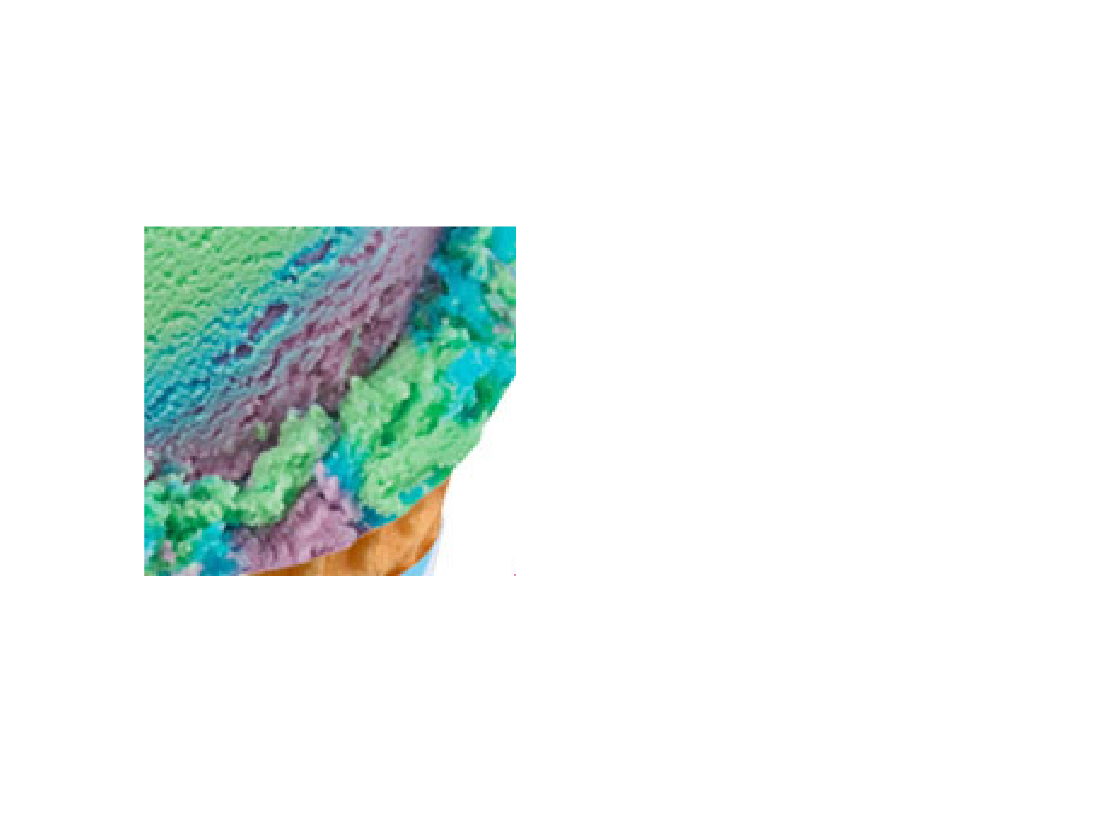

B_os = uint8(B_os);
subplot(1,2,2), imshow(B_os)